# Intracellular electrophysiology

The following tutorial describes storage of intracellular electrophysiology data in NWB. NWB supports storage of the time series describing the stimulus and response, information about the electrode and device used, as well as metadata about the organization of the experiment.

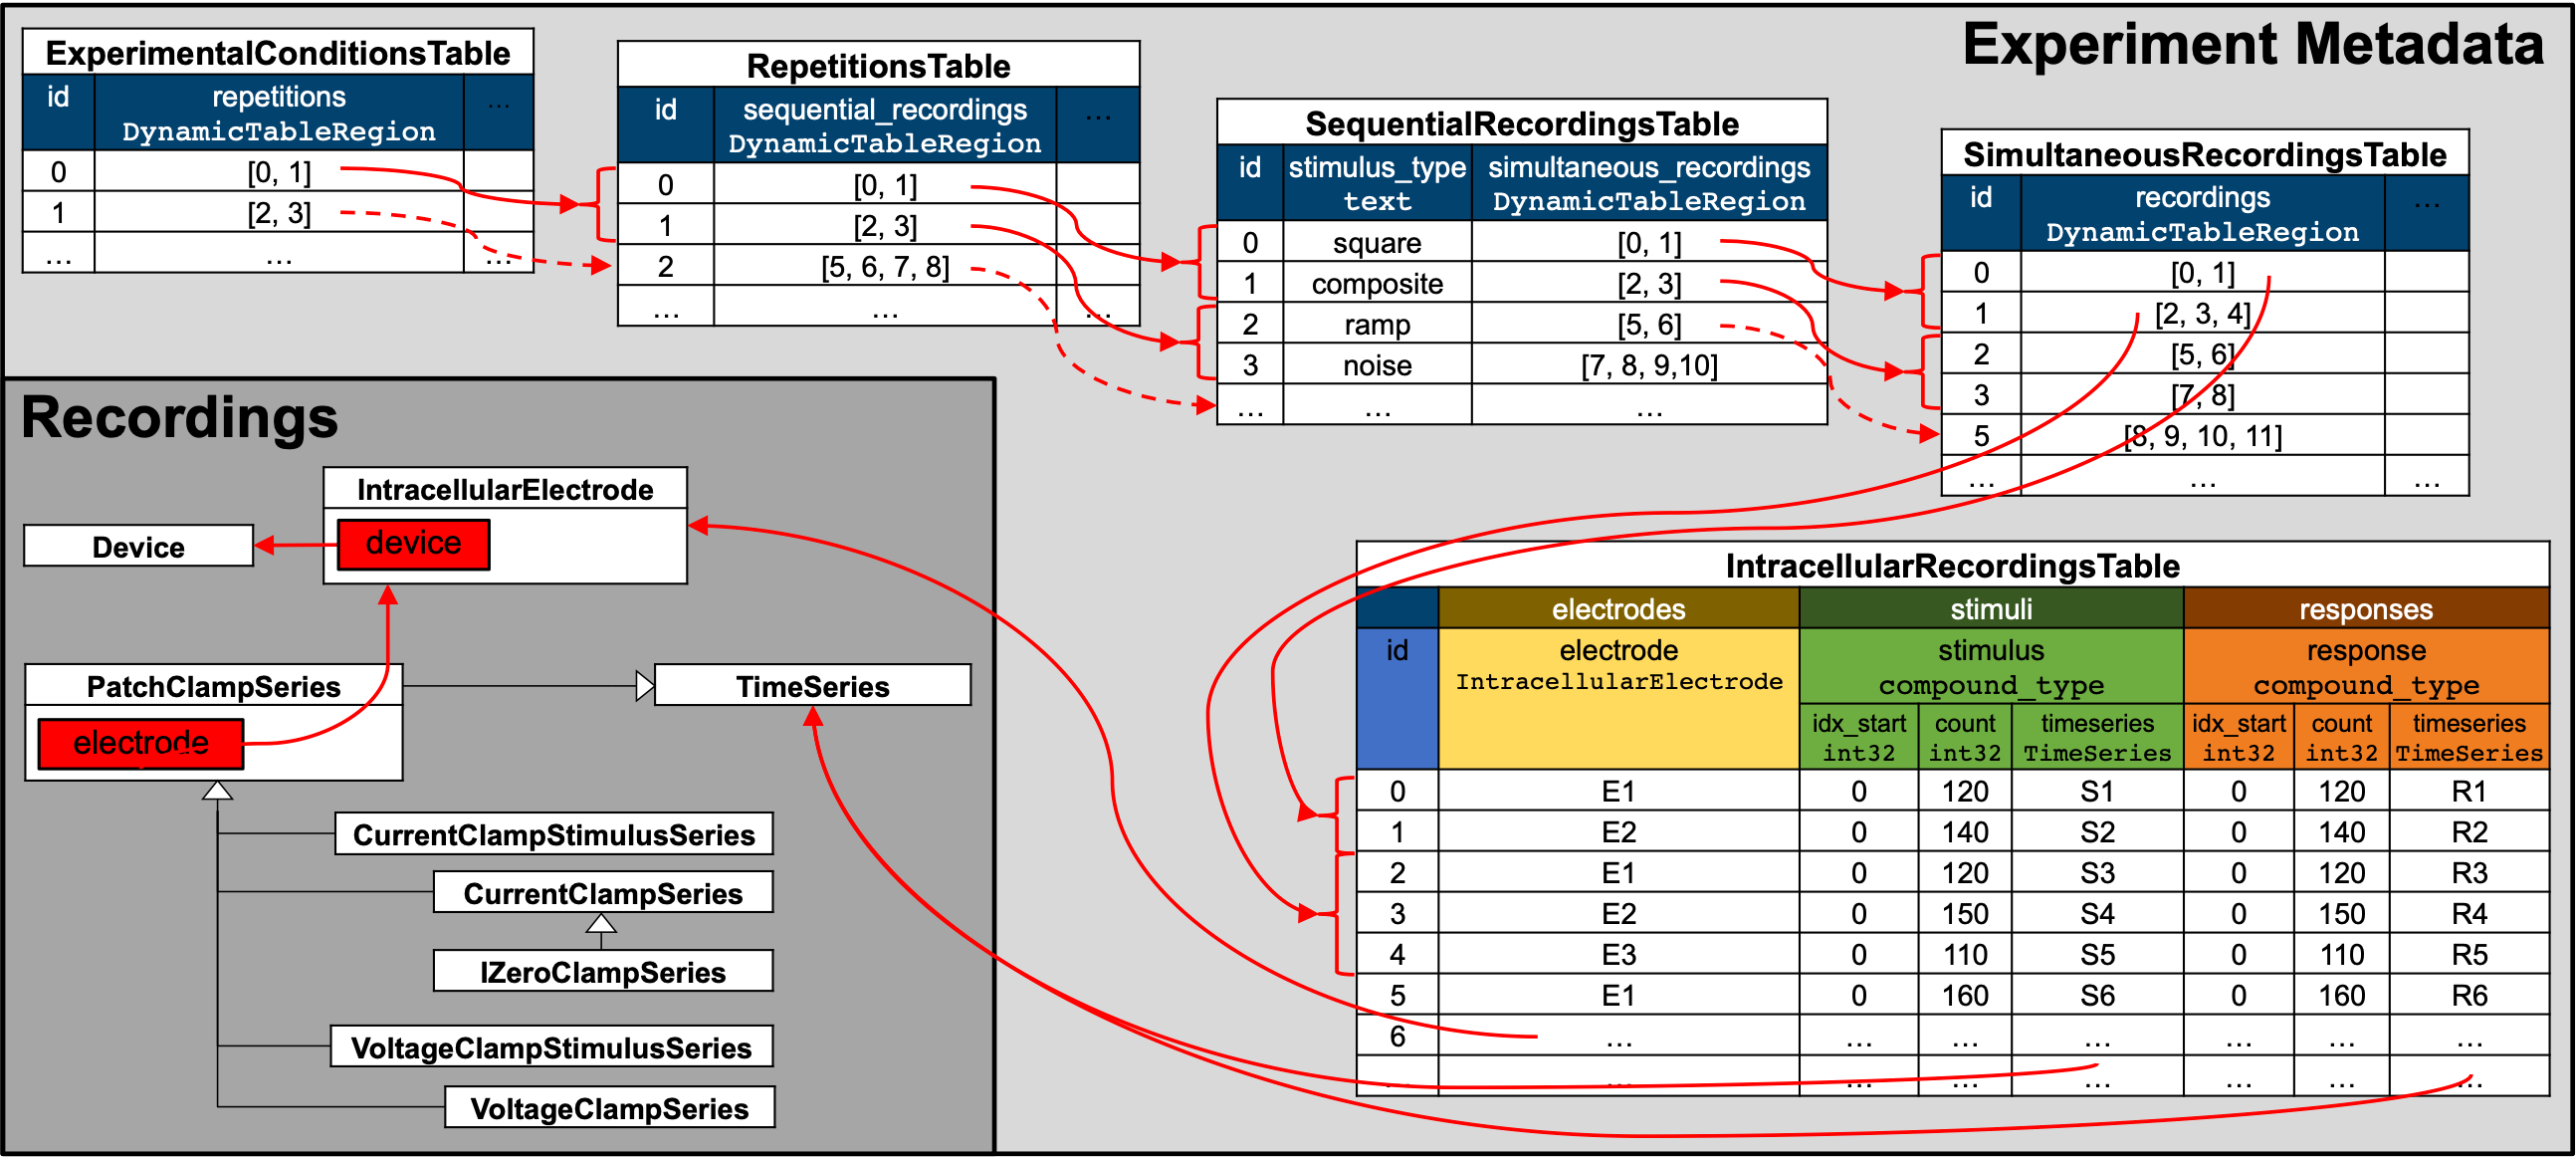

*Illustration of the hierarchy of metadata tables used to describe the organization of intracellular electrophysiology experiments.*

## Creating an NWBFile

When creating an NWB file, the first step is to create the [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/NWBFile.html), which you can create using the [`NwbFile`](https://neurodatawithoutborders.github.io/matnwb/doc/NwbFile.html) command.

session_start_time = datetime(2018, 3, 1, 12, 0, 0, 'TimeZone', 'local');


nwbfile = NwbFile( ...
    'session_description', 'my first synthetic recording', ...
    'identifier', 'EXAMPLE_ID', ...
    'session_start_time', session_start_time, ...
    'general_experimenter', 'Dr. Bilbo Baggins', ...
    'general_lab', 'Bag End Laboratory', ...
    'general_institution', 'University of Middle Earth at the Shire', ...
    'general_experiment_description', 'I went on an adventure with thirteen dwarves to reclaim vast treasures.', ...
    'general_session_id', 'LONELYMTN' ...
);


### Device metadata

Device metadata is represented by [`Device`](https://pynwb.readthedocs.io/en/stable/pynwb.device.html#pynwb.device.Device) objects.


device = types.core.Device();
nwbfile.general_devices.set('Heka ITC-1600', device);

### **Electrode metadata**

Intracellular electrode metadata is represented by [`IntracellularElectrode`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/IntracellularElectrode.html) objects. Create an electrode object, which requires a link to the device of the previous step. Then add it to the NWB file.

electrode = types.core.IntracellularElectrode( ...
    'description', 'a mock intracellular electrode', ...
    'device', types.untyped.SoftLink(device) ...
);
nwbfile.general_intracellular_ephys.set('elec0', electrode);

## **Stimulus and response data**

Intracellular stimulus and response data are represented with subclasses of [`PatchClampSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/PatchClampSeries.html). A stimulus is described by a time series representing voltage or current stimulation with a particular set of parameters. There are two classes for representing stimulus data:

- [`VoltageClampStimulusSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/VoltageClampStimulusSeries.html)

- [`CurrentClampStimulusSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/CurrentClampStimulusSeries.html)

The response is then described by a time series representing voltage or current recorded from a single cell using a single intracellular electrode via one of the following classes:

- [`VoltageClampSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/VoltageClampSeries.html)

- [`CurrentClampSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/CurrentClampSeries.html)

- [`IZeroClampSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/IZeroClampSeries.html)

Below we create a simple example stimulus/response recording data pair.

ccss = types.core.VoltageClampStimulusSeries( ...
    'data', [1, 2, 3, 4, 5], ...
    'starting_time', 123.6, ...
    'starting_time_rate', 10e3, ...
    'electrode', types.untyped.SoftLink(electrode), ...
    'gain', 0.02, ...
    'sweep_number', uint64(15), ...
    'stimulus_description', 'N/A' ...
);

nwbfile.stimulus_presentation.set('ccss',  ccss);

vcs = types.core.VoltageClampSeries( ...
    'data', [0.1, 0.2, 0.3, 0.4, 0.5], ...
    'data_conversion', 1e-12, ...
    'data_resolution', NaN, ...
    'starting_time', 123.6, ...
    'starting_time_rate', 20e3, ...
    'electrode', types.untyped.SoftLink(electrode), ...
    'gain', 0.02, ...
    'capacitance_slow', 100e-12, ...
    'resistance_comp_correction', 70.0, ...
    'stimulus_description', 'N/A', ...
    'sweep_number', uint64(15) ...
);
nwbfile.acquisition.set('vcs',  vcs);

### Adding an intracellular recording

The [`IntracellularRecordingsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/IntracellularRecordingsTable.html) relates electrode, stimulus and response pairs and describes metadata specific to individual recordings.

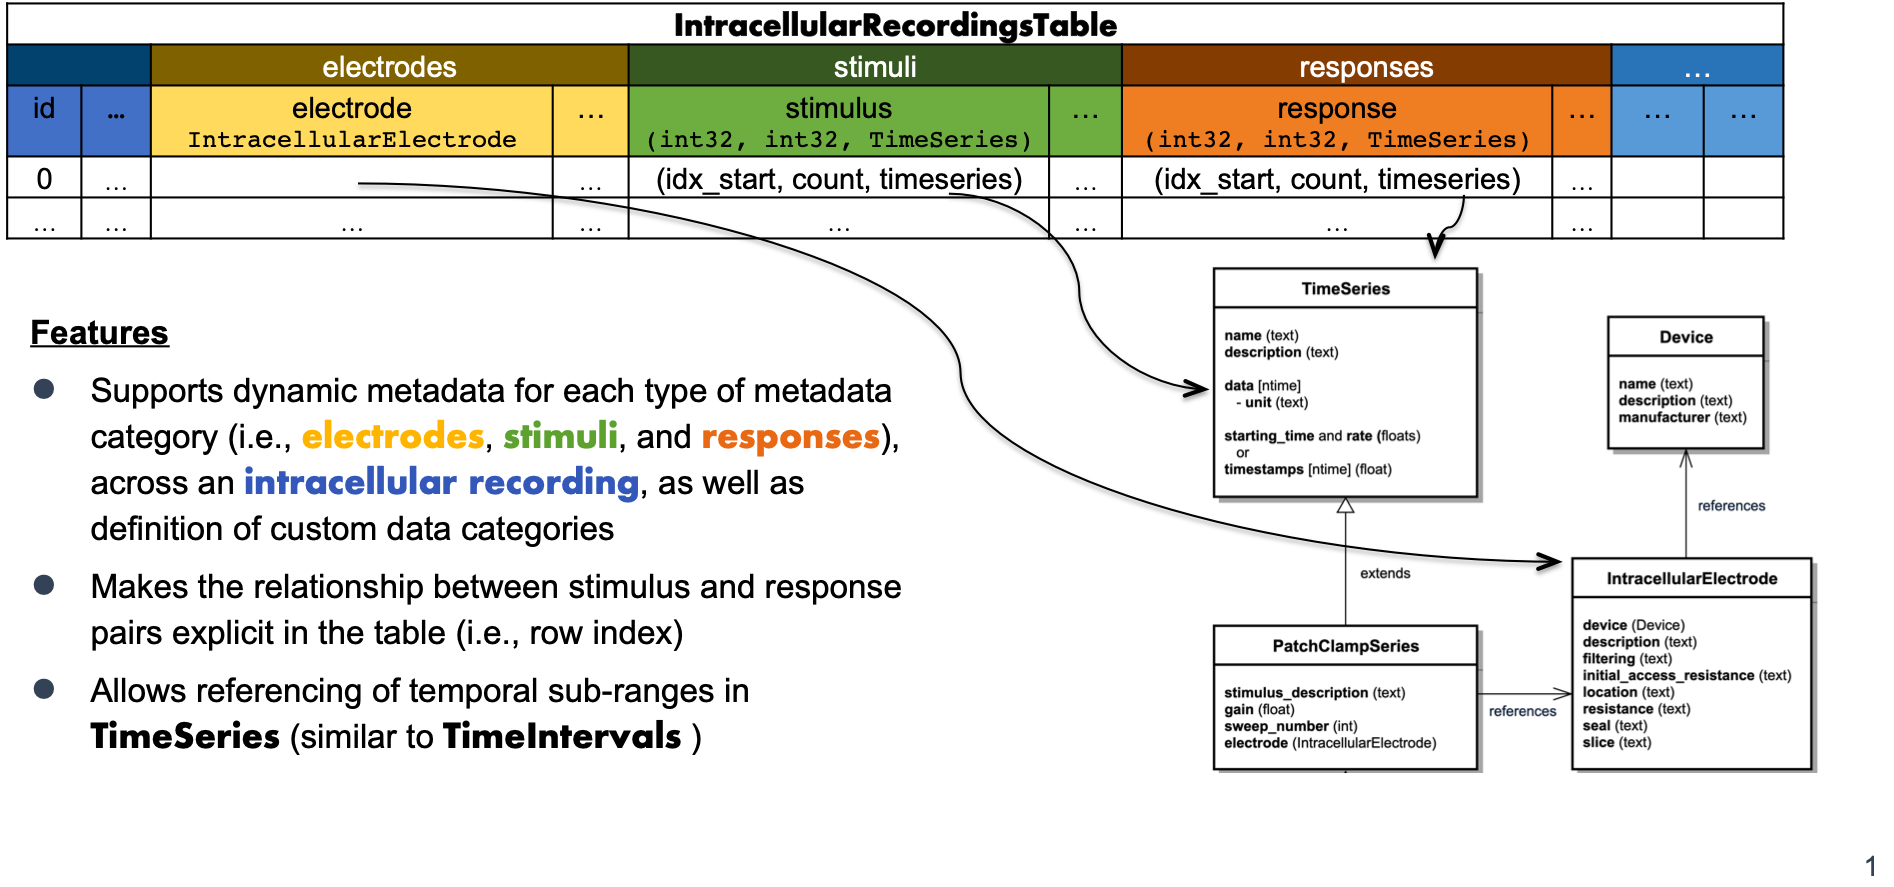

*Illustration of the structure of the IntracellularRecordingsTable*

We can add an [`IntracellularRecordingsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/IntracellularRecordingsTable.html) and add the [`IntracellularElectrodesTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/IntracellularElectrodesTable.html), [`IntracellularStimuliTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/IntracellularStimuliTable.html), and [`IntracellularResponsesTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/IntracellularResponsesTable.html) to it, then add them all to the [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/NWBFile.html) object.

ic_rec_table = types.core.IntracellularRecordingsTable( ...
    'categories', {'electrodes', 'stimiuli', 'responses'}, ...
    'colnames', {'recordings_tag'}, ...
    'description', [ ...
        'A table to group together a stimulus and response from a single ', ...
        'electrode and a single simultaneous recording and for storing ', ...
        'metadata about the intracellular recording.'], ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64([10, 11, 12]) ...
    ) ...
);

ic_rec_table.electrodes = types.core.IntracellularElectrodesTable( ...
    'description', 'Table for storing intracellular electrode related metadata.', ...
    'colnames', {'electrode'}, ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64([0, 1, 2]) ...
    ), ...
    'electrode', types.hdmf_common.VectorData( ...
        'data', repmat(types.untyped.ObjectView(electrode), 3, 1), ...
        'description', 'Column for storing the reference to the intracellular electrode' ...
    ) ...
);

ic_rec_table.stimuli = types.core.IntracellularStimuliTable( ...
    'description', 'Table for storing intracellular stimulus related metadata.', ...
    'colnames', {'stimulus'}, ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64([0, 1, 2]) ...
    ), ...
    'stimulus', types.core.TimeSeriesReferenceVectorData( ...
        'description', 'Column storing the reference to the recorded stimulus for the recording (rows)', ...
        'data', struct( ...
            'idx_start', [0, 1, -1], ...
            'count', [5, 3, -1], ...
            'timeseries', [ ...
                types.untyped.ObjectView(ccss), ...
                types.untyped.ObjectView(ccss), ...
                types.untyped.ObjectView(vcs) ...
            ] ...
        )...
    )...
);

ic_rec_table.responses = types.core.IntracellularResponsesTable( ...
    'description', 'Table for storing intracellular response related metadata.', ...
    'colnames', {'response'}, ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64([0, 1, 2]) ...
    ), ...
    'response', types.core.TimeSeriesReferenceVectorData( ...
        'description', 'Column storing the reference to the recorded response for the recording (rows)', ...
        'data', struct( ...
            'idx_start', [0, 2, 0], ...
            'count', [5, 3, 5], ...
            'timeseries', [ ...
                types.untyped.ObjectView(vcs), ...
                types.untyped.ObjectView(vcs), ...
                types.untyped.ObjectView(vcs) ...
            ] ...
        )...
    )...
);


The [`IntracellularRecordingsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/IntracellularRecordingsTable.html) table is not just a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) but an [`AlignedDynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/AlignedDynamicTable.html)`.` The [`AlignedDynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/AlignedDynamicTable.html) type is itself a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) that may contain an arbitrary number of additional [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), each of which defines a "category." This is similar to a table with “sub-headings”. In the case of the [`IntracellularRecordingsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/IntracellularRecordingsTable.html), we have three predefined categories, i.e., electrodes, stimuli, and responses. We can also dynamically add new categories to the table. As each category corresponds to a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), this means we have to create a new [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) and add it to our table.

% add category
ic_rec_table.categories = [ic_rec_table.categories, {'recording_lab_data'}];
ic_rec_table.dynamictable.set( ...
    'recording_lab_data', types.hdmf_common.DynamicTable( ...
        'description', 'category table for lab-specific recording metadata', ...
        'colnames', {'location'}, ...
        'id', types.hdmf_common.ElementIdentifiers( ...
            'data', int64([0, 1, 2]) ...
        ), ...
        'location', types.hdmf_common.VectorData( ...
            'data', {'Mordor', 'Gondor', 'Rohan'}, ...
            'description', 'Recording location in Middle Earth' ...
        ) ...
    ) ...
);

In an [`AlignedDynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/AlignedDynamicTable.html) all category tables must align with the main table, i.e., all tables must have the same number of rows and rows are expected to correspond to each other by index.

We can also add custom columns to any of the subcategory tables, i.e., the electrodes, stimuli, and responses tables, and any custom subcategory tables. All we need to do is indicate the name of the category we want to add the column to.

% Add voltage threshold as column of electrodes table
ic_rec_table.electrodes.colnames = [ic_rec_table.electrodes.colnames {'voltage_threshold'}];
ic_rec_table.electrodes.vectordata.set('voltage_threshold', types.hdmf_common.VectorData( ...
    'data', [0.1, 0.12, 0.13], ...
    'description', 'Just an example column on the electrodes category table' ...
    ) ...
);

nwbfile.general_intracellular_ephys_intracellular_recordings = ic_rec_table;

## Hierarchical organization of recordings

To describe the organization of intracellular experiments, the metadata is organized hierarchically in a sequence of tables. All of the tables are so-called DynamicTables enabling users to add columns for custom metadata. Storing data in hierarchical tables has the advantage that it allows us to avoid duplication of metadata. E.g., for a single experiment we only need to describe the metadata that is constant across an experimental condition as a single row in the [`SimultaneousRecordingsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SimultaneousRecordingsTable.html) without having to replicate the same information across all repetitions and sequential-, simultaneous-, and individual intracellular recordings. For analysis, this means that we can easily focus on individual aspects of an experiment while still being able to easily access information about information from related tables. All of these tables are optional, but to use one you must use all of the lower level tables, even if you only need a single row.

### Add a simultaneous recording

The [`SimultaneousRecordingsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SimultaneousRecordingsTable.html) groups intracellular recordings from the [`IntracellularRecordingsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/IntracellularRecordingsTable.html) together that were recorded simultaneously from different electrodes and/or cells and describes metadata that is constant across the simultaneous recordings. In practice a simultaneous recording is often also referred to as a sweep. This example adds a custom column, "simultaneous_recording_tag."

% create simultaneous recordings table with custom column
% 'simultaneous_recording_tag'

[recordings_vector_data, recordings_vector_index] = util.create_indexed_column( ...
    {[0, 1, 2],}, ...
    'Column with references to one or more rows in the IntracellularRecordingsTable table', ...
    ic_rec_table);

ic_sim_recs_table = types.core.SimultaneousRecordingsTable( ...
    'description', [ ...
        'A table for grouping different intracellular recordings from ', ...
        'the IntracellularRecordingsTable table together that were recorded ', ...
        'simultaneously from different electrodes.'...
    ], ...
    'colnames', {'recordings', 'simultaneous_recording_tag'}, ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64(12) ...
    ), ...
    'recordings', recordings_vector_data, ...
    'recordings_index', recordings_vector_index, ...
    'simultaneous_recording_tag', types.hdmf_common.VectorData( ...
        'description', 'A custom tag for simultaneous_recordings', ...
        'data', {'LabTag1'} ...
    ) ...
);


Depending on the lab workflow, it may be useful to add complete columns to a table after we have already populated the table with rows. That would be done like so:

ic_sim_recs_table.colnames = [ic_sim_recs_table.colnames, {'simultaneous_recording_type'}];
ic_sim_recs_table.vectordata.set( ...
    'simultaneous_recording_type', types.hdmf_common.VectorData(...
        'description', 'Description of the type of simultaneous_recording', ...
        'data', {'SimultaneousRecordingType1'} ...
    ) ...
);

nwbfile.general_intracellular_ephys_simultaneous_recordings = ic_sim_recs_table;

### Add a sequential recording

The [`SequentialRecordingsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SequentialRecordingsTable.html) groups simultaneously recorded intracellular recordings from the [`SimultaneousRecordingsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SimultaneousRecordingsTable.html) together and describes metadata that is constant across the simultaneous recordings. In practice a sequential recording is often also referred to as a sweep sequence. A common use of sequential recordings is to group together simultaneous recordings where a sequence of stimuli of the same type with varying parameters have been presented in a sequence (e.g., a sequence of square waveforms with varying amplitude).

[simultaneous_recordings_vector_data, simultaneous_recordings_vector_index] = util.create_indexed_column( ...
    {0,}, ...
    'Column with references to one or more rows in the SimultaneousRecordingsTable table', ...
    ic_sim_recs_table);

sequential_recordings = types.core.SequentialRecordingsTable( ...
    'description', [ ...
        'A table for grouping different intracellular recording ', ...
        'simultaneous_recordings from the SimultaneousRecordingsTable ', ...
        'table together. This is typically used to group together ', ...
        'simultaneous_recordings where the a sequence of stimuli of ', ...
        'the same type with varying parameters have been presented in ', ...
        'a sequence.' ...
    ], ...
    'colnames', {'simultaneous_recordings', 'stimulus_type'}, ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64(15) ...
    ), ...
    'simultaneous_recordings', simultaneous_recordings_vector_data, ...
    'simultaneous_recordings_index', simultaneous_recordings_vector_index, ...
    'stimulus_type', types.hdmf_common.VectorData( ...
        'description', 'Column storing the type of stimulus used for the sequential recording', ...
        'data', {'square'} ...
    ) ...
);

nwbfile.general_intracellular_ephys_sequential_recordings = sequential_recordings;

### Add repetitions table

The [`RepetitionsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/RepetitionsTable.html) groups sequential recordings from the [`SequentialRecordingsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SequentialRecordingsTable.html). In practice, a repetition is often also referred to a run. A typical use of the [`RepetitionsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/RepetitionsTable.html) is to group sets of different stimuli that are applied in sequence that may be repeated.

[sequential_recordings_vector_data, sequential_recordings_vector_index] = util.create_indexed_column( ...
    {0,}, ...
    'Column with references to one or more rows in the SequentialRecordingsTable table', ...
    sequential_recordings);


nwbfile.general_intracellular_ephys_repetitions = types.core.RepetitionsTable( ...
    'description', [ ...
        'A table for grouping different intracellular recording sequential ', ...
        'recordings together. With each SimultaneousRecording typically ', ...
        'representing a particular type of stimulus, the RepetitionsTable ', ...
        'table is typically used to group sets of stimuli applied in sequence.' ...
    ], ...
    'colnames', {'sequential_recordings'}, ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64(17) ...
    ), ...
    'sequential_recordings', sequential_recordings_vector_data, ...
    'sequential_recordings_index', sequential_recordings_vector_index ...
);

### Add experimental condition table

The [`ExperimentalConditionsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ExperimentalConditionsTable.html) groups repetitions of intracellular recording from the [`RepetitionsTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/RepetitionsTable.html) together that belong to the same experimental conditions.

[repetitions_vector_data, repetitions_vector_index] = util.create_indexed_column( ...
    {0, 0}, ...
    'Column with references to one or more rows in the RepetitionsTable table', ...
    nwbfile.general_intracellular_ephys_repetitions);

nwbfile.general_intracellular_ephys_experimental_conditions = types.core.ExperimentalConditionsTable( ...
    'description', [ ...
        'A table for grouping different intracellular recording ', ...
        'repetitions together that belong to the same experimental ', ...
        'conditions.' ...
    ], ...
    'colnames', {'repetitions', 'tag'}, ...
    'id', types.hdmf_common.ElementIdentifiers( ...
        'data', int64([19, 21]) ...
    ), ...
    'repetitions', repetitions_vector_data, ...
    'repetitions_index', repetitions_vector_index, ...
    'tag', types.hdmf_common.VectorData( ...
        'description', 'integer tag for a experimental condition', ...
        'data', [1,3] ...
    ) ...
);

## Write the NWB file

nwbExport(nwbfile, 'test_new_icephys.nwb');

## Read the NWB file

nwbfile2 = nwbRead('test_new_icephys.nwb')

nwbfile2 =   NwbFile with properties:

                                             nwb_version: '2.4.0'
                                             acquisition: [1×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                        file_create_date: [1×1 types.untyped.DataStub]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: []
                                         general_devices: [1×1 types.untyped.Set]
                          general_experiment_description: 'I went on an adventure with thirteen dwarves to reclaim vast treasures.'
                                    general_experimenter: [1×1 types.untyped.DataStub]
                             general_extracellular_ephys: [0×1 types.untyped.Set]
                  general_extracellular_ephys_electrod